%Load the dataset
data = load("visiblehuman.mat");
dataHead = data.head;
dataFresh = data.head_fresh;
dataFrozen = data.head_frozen;
dataMR = data.head_mri;

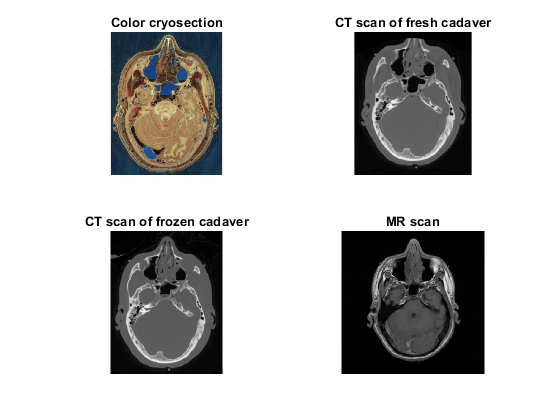

%Visualize the data
figure();
subplot(2, 2, 1);
imshow(dataHead), title("Color cryosection");
subplot(2, 2, 2);
imshow(dataFresh), title("CT scan of fresh cadaver");
subplot(2, 2, 3);
imshow(dataFrozen), title("CT scan of frozen cadaver");
subplot(2, 2, 4);
imshow(dataMR), title("MR scan");

%Load the annotated points
data1 = load("SelPointsG.mat");
data2 = load("SelPointsM.mat");
data3 = load("SelPointsZ.mat");
CryoAll = zeros([10 2 3]);
CryoAll(:, :, 1) = data1.ColCryoPoints;
CryoAll(:, :, 2) = data2.movingPoints;
CryoAll(:, :, 3) = data3.ColCryoPoints;
CT1 = data1.CTFreshPoints;
data2.movingPoints - data3.ColCryoPoints

ans =     1.1639    4.3552
    4.9542    4.8384
    0.6659   -1.0035
    2.4188   -2.5490
    0.2420    0.3802
    7.5062   -1.1198
    7.3357   -9.7993
    2.8896    1.6235
   -0.4504    3.8395
    7.7720    0.8459


%Visualize the color cryosection annotations
figure();
imshow(dataHead);
hold on;
for i = 1:3
    plot(CryoAll(:, 1, i), CryoAll(:, 2, i), '.', "MarkerSize", 25);
end

%Calculate the mean landmark
CryoMean = mean(CryoAll, 3)

CryoMean =   341.6540   87.6385
  403.9319  105.6372
  509.1947  359.2512
  501.6104  486.5997
  294.3360  685.4566
  261.9146  684.9566
   36.9714  483.8498
   34.2868  348.8755
  134.7335  102.3035
  215.8260   82.4680


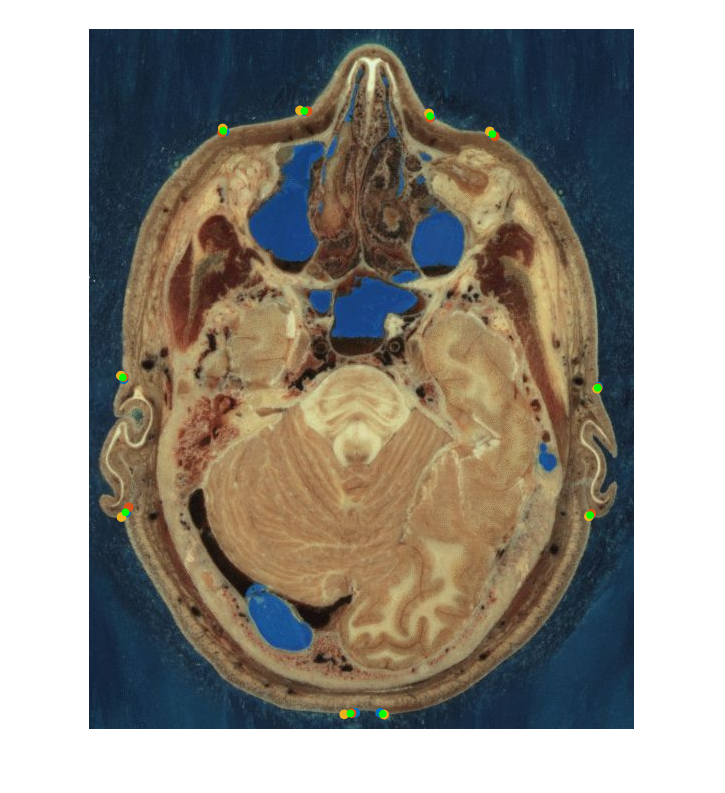

plot(CryoMean(:, 1), CryoMean(:, 2), 'g.', "MarkerSize", 20);


%Calculate the Fiducial localization erro (FLE)
[f, sig] = FeducialLocalizationError(CryoAll)

f =     5.3420   -0.5879
   -0.5879    3.2187


sig = 4.2804


F = [0 0; 0 0];
for i = 1:size(CryoAll, 1)
    for j = 1:size(CryoAll, 3)
        F = F + (CryoAll(i, :, j) - CryoMean(i, :)) * (CryoAll(i, :, j) - CryoMean(i, :))';
    end
end
disp(F);

  256.8213  256.8213
  256.8213  256.8213



disp(F / 30)

    8.5607    8.5607
    8.5607    8.5607

